# Riccati equation


$$\dot{u} =u^2 -u$$


clearvars; format long; addpath("functions/")

## Vector field lines

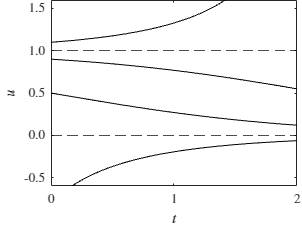

syms u0 ; syms u_teo(t,uo)
u_teo(t,u0) = ((1-u0)*u0^(-1)*exp(t)+1)^-1;
u_teo = matlabFunction(u_teo);
u0_test = [-0.8 0.5 0.9 1.1];

figure; tiledlayout(1,1,'TileSpacing','tight','Padding','tight');
nexttile; hold on
for k = 1:length(u0_test)
    fplot(u_teo(t,u0_test(k)),[0 2],'showPoles','off','Color','k')
end
yline(0,'--k'); yline(1,'--k');
xlabel('$t$','Interpreter','latex')
ylabel('$u$','Interpreter','latex')
ylim([-0.6 1.6]); yticks([-0.5 0 0.5 1.0 1.5]); ytickformat('%.1f'); 
xlim([0 2]); xticks([0 1 2]);
set(gca,'FontSize',10,'TickLabelInterpreter','latex'); box on
set(gcf,'renderer','Painters','Units','centimeters','Position',[0 0 8 6]);

## Approximants

### Around u = 0 (N = 2 y 3)

[A,~,x0] = MatA_u(2,u0); M = expm(A*t); X = formula(M*x0); u_eq0_N2 = matlabFunction(X(1),'vars', [t u0]); lambdaA_0N2 = eig(A); clear A x0 M X
[A,~,x0] = MatA_u(3,u0); M = expm(A*t); X = formula(M*x0); u_eq0_N3 = matlabFunction(X(1),'vars', [t u0]); lambdaA_0N3 = eig(A); clear A x0 M X

### Around u = 1 (N = 2 y 3)

[A,Vars,x0] = MatA_x(2, u0); M = expm(A*t); X = formula(M*x0); u_eq1_N2 = matlabFunction(1+X(Vars == 'x1'),'Vars',[t u0]); lambdaA_1N2 = eig(A); clear A x0 M X
[A,Vars,x0] = MatA_x(3, u0); M = expm(A*t); X = formula(M*x0); u_eq1_N3 = matlabFunction(1+X(Vars == 'x1'),'Vars',[t u0]); lambdaA_1N3 = eig(A); clear A x0 M X

### Around u = u0 (N = 2)

[A,Vars,~,b] = MatA_u0(2,u0,u0); M = expm(A*t); invA = inv(A); X = invA*(M-eye(size(M)))*b; lambdaA_u0N2 = eig(A); %#ok<*MINV> 
u_u0 = matlabFunction(u0 + simplify(X(Vars == 'x1')),'Vars',[t u0]); 
clearvars -except N  u_eq0_N3 u_eq0_N2 u_eq1_N3 u_eq1_N2 u_u0 u_teo u0_test lambdaA_0N2 lambdaA_0N3 lambdaA_1N2 lambdaA_1N3 lambdaA_u0N2

## Plot preparation

t = [0 10.^linspace(-7,log10(20),10000)]'; Lim = 0.25;
Yplot_eq0_N2{length(u0_test)} = [];  Yplot_eq1_N2{length(u0_test)} = []; Yplot_u0{length(u0_test)} = []; 
Yplot_eq0_N3{length(u0_test)} = [];  Yplot_eq1_N3{length(u0_test)} = [];
for i = 1:length(u0_test)
    Yplot_eq0_N2{i} = distLim_plot_Riccati(t,u_teo(t,u0_test(i)),u_eq0_N2(t,u0_test(i)),Lim);
    Yplot_eq0_N3{i} = distLim_plot_Riccati(t,u_teo(t,u0_test(i)),u_eq0_N3(t,u0_test(i)),Lim);
    Yplot_eq1_N2{i} = distLim_plot_Riccati(t,u_teo(t,u0_test(i)),u_eq1_N2(t,u0_test(i)),Lim);
    Yplot_eq1_N3{i} = distLim_plot_Riccati(t,u_teo(t,u0_test(i)),u_eq1_N3(t,u0_test(i)),Lim);
    Yplot_u0{i} = distLim_plot_Riccati(t,u_teo(t,u0_test(i)),u_u0(t,u0_test(i)),Lim);
end; clear i


## Results

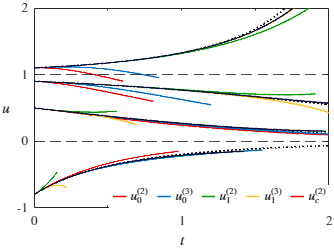

%%% Some plot options %%%%
grey = [0.854901960784314,0.890196078431373,0.949019607843137]; green = [0,0.600000000000000,0.003921568627451];
blue = [0.007843137254902,0.439215686274510,0.752941176470588]; color4 = [0.035294117647059,0.050980392156863,0.215686274509804];
yellow_wa = [1,0.752941176470588,0.149019607843137]; red = [0.917647058823529,0,0.015686274509804];dotSize = 5; fontSize = 10; 
black = [0.035294117647059,0.050980392156863,0.215686274509804]; alpha_C = 0.9; alpha_teo = 0.85; lineWidth_teo = 1.15; lineWidth = 1.15; lineStyle_teo = ":";
%%%%%%%%%%%%%%%%%%%%%%%%%%

figure; tiledlayout(1,1,'TileSpacing','tight','Padding','tight');
nexttile; hold on
for k = 1:length(u0_test)
    plot(t,u_teo(t,u0_test(k)),'Color','k','LineStyle',lineStyle_teo,'LineWidth',lineWidth_teo,'HandleVisibility','off')
    plot(Yplot_eq0_N2{k}(:,1),Yplot_eq0_N2{k}(:,2),'Color',[red alpha_C],'LineWidth',lineWidth)
    plot(Yplot_eq0_N3{k}(:,1),Yplot_eq0_N3{k}(:,2),'Color',[blue alpha_C],'LineWidth',lineWidth)
    plot(Yplot_eq1_N2{k}(:,1),Yplot_eq1_N2{k}(:,2),'Color',[green alpha_C],'LineWidth',lineWidth)
    plot(Yplot_eq1_N3{k}(:,1),Yplot_eq1_N3{k}(:,2),'Color',[yellow_wa alpha_C],'LineWidth',lineWidth)
    plot(Yplot_u0{k}(:,1),Yplot_u0{k}(:,2),'Color',[black alpha_C],'LineWidth',lineWidth,'HandleVisibility','off')
end
yline(0,'--k'); yline(1,'--k');
xlabel('$t$','Interpreter','latex')
ylabel('$u$','Interpreter','latex','Rotation',0,'HorizontalAlignment','right','VerticalAlignment','middle')
ylim([-1 2]); yticks([-1 0 1 2]); xlim([0 2]); xticks([0 0.5 1 1.5 2]); xticklabels({'0','','1','','2'})
leg = legend({'$u_0^{(2)}$','$u_0^{(3)}$','$u_1^{(2)}$','$u_1^{(3)}$','$u_c^{(2)}$'},'Interpreter','latex',...
    'FontSize',fontSize,'box','off','Orientation','horizontal',... %'Location','southeast'); 
    'Position',[0.3269 0.1645 0.6670 0.0913]); leg.ItemTokenSize(1) = 10; 
set(gca,'FontSize',fontSize,'TickLabelInterpreter','latex'); box on
set(gcf,'renderer','Painters','Units','centimeters','Position',[0,0,8.85,6.6]);

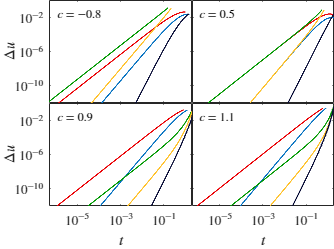

figure; tiledlayout(2,2,'TileSpacing','none','Padding','tight');
for k = 1:length(u0_test)
nexttile; hold on
    plot(Yplot_eq0_N2{k}(:,1),Yplot_eq0_N2{k}(:,3),'Color',[red alpha_C],'LineWidth',lineWidth)
    plot(Yplot_eq0_N3{k}(:,1),Yplot_eq0_N3{k}(:,3),'Color',[blue alpha_C],'LineWidth',lineWidth)
    plot(Yplot_eq1_N2{k}(:,1),Yplot_eq1_N2{k}(:,3),'Color',[green alpha_C],'LineWidth',lineWidth)
    plot(Yplot_eq1_N3{k}(:,1),Yplot_eq1_N3{k}(:,3),'Color',[yellow_wa alpha_C],'LineWidth',lineWidth)
    plot(Yplot_u0{k}(:,1),Yplot_u0{k}(:,3),'Color',[black alpha_C],'LineWidth',lineWidth)
text(10^(-6),10^(-1.5),"$c = "+num2str(u0_test(k),2)+"$",'interpreter','latex','FontSize',fontSize-1)
ylim(10.^[-12 0.1]); yticks(10.^[-10 -6 -2]); xlim([5*10^-7 2]); xticks(10.^[-5 -3 -1])
set(gca,'XScale','log','YScale','log','FontSize',fontSize,'TickLabelInterpreter','latex','XMinorTick','on','YMinorTick','on'); box on
ax = gca; ax.XAxis.MinorTickValues = 10.^[-6 -4 -2 0]; ax.YAxis.MinorTickValues = 10.^(-12:1:-1); 
if mod(k,2) == 1; ylabel('$\Delta u$','Interpreter','latex','VerticalAlignment','middle'); else; yticklabels(''); end
if k > 2; xlabel('$t$','Interpreter','latex'); else; xticklabels(''); end
end
set(gcf,'renderer','Painters','Units','centimeters','Position',[0,0,8.85,6.6]);